%Least square approximation for power functon
%Enter x and y in array form
% 𝑦 = alpha*x^(beta): We will get alpha and beta though least square approximation ans=r^2 =(Em-Else)/Else where 𝐸lse =∑(𝑦𝑖 − 𝑎1∗𝑥𝑖 − 𝑎0)^2 and  𝐸m = ∑(𝑦𝑖 − 𝑦̅)^2 where 𝑦̅ =∑ 𝑦𝑖/𝑛  and 𝑖=1 to n
%coefficient of determination, 𝑟^2 is defined as the relative error between 𝐸m and 𝐸lse
x=[1 2 3 4 5 6 7 8];
y=[2.5 7 38 55 61 122 83 143];
xe=log(x);
ye=log(y);
n=length(x);
a1=(n*sum(xe.*ye)-sum(xe)*sum(ye))/(n*sum(xe.^2)-(sum(xe)).^2);
a0=sum(ye)/n-a1*sum(xe)/n;
r=(n*sum(xe.*ye)-sum(xe)*sum(ye))/((sqrt(n*sum(xe.^2)-(sum(xe))^2))*(sqrt(n*sum(ye.^2)-(sum(ye))^2)));
alpha=exp(a0), beta=a1

alpha =    2.649298576963049


beta =    1.981153017169898


r^2;

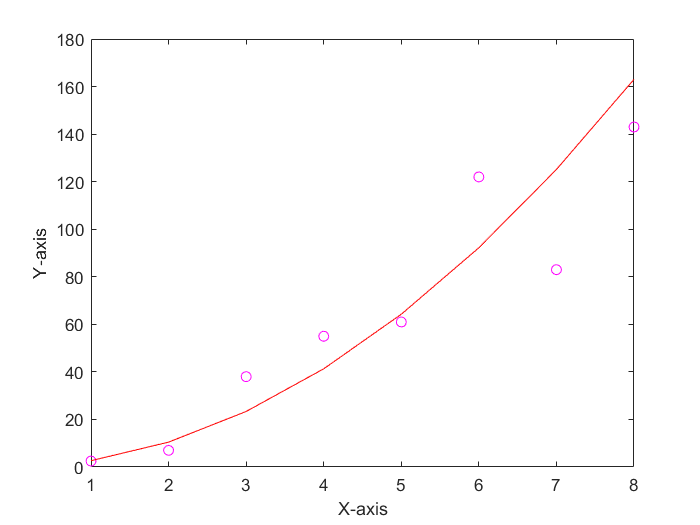

%plotting section
plot(x,y,"mo")
f= alpha*x.^beta;
xlabel('X-axis')
ylabel('Y-axis')
hold on
plot(x,f,"-r")
hold off


%xlim([min(x) max(x)+2])
%ylim([min(y)-2 max(y)+2])